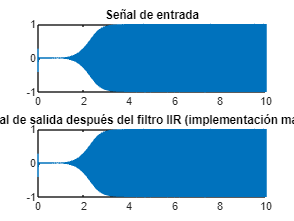

clear
% Coeficientes del numerador y denominador
b = [ 0.268935721618647038955174366492428816855
-1.344678608093235139264720601204317063093
 2.689357216186470722618651052471250295639
-2.689357216186470722618651052471250295639
 1.344678608093235139264720601204317063093
-0.268935721618647038955174366492428816855
];  % Coeficientes del numerador
a = [ 1                                        
-2.474416174978162796804781464743427932262
 2.811006311911582233875606107176281511784
-1.703772240915468305644253632635809481144
 0.544432694888534185473361048934748396277
-0.072315669102958543557058135320403380319
];  % Coeficientes del denominador


% Generar una señal de entrada de ejemplo
fs = 60000;
t =0:1/fs:10;
x = chirp(t,1,1,3000);

y = zeros(size(x));

% Aplicar el filtro IIR
salida = filtro_IIR_manual(x, b.', a.');
salida2 = filtro_IIR(x, b.', a.');

% Graficar la señal de entrada y la salida
figure;
subplot(2,1,1);
plot(t, salida);
title('Señal de entrada');

subplot(2,1,2);
plot(t, salida2);
title('Señal de salida después del filtro IIR (implementación manual)');

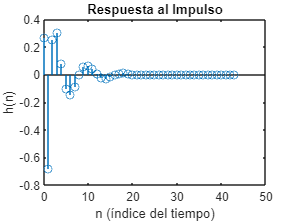


% Calcular la respuesta al impulso
h = impz(b.', a.');

% Graficar la respuesta al impulso
figure;
stem(0:length(h)-1, h);
title('Respuesta al Impulso');
xlabel('n (índice del tiempo)');
ylabel('h(n)');

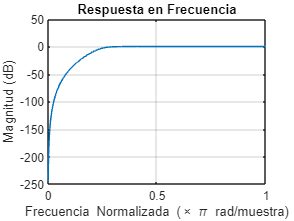


figure;
[n, w] = freqz(b, a, 1024);  % Especifica 1024 puntos en la respuesta en frecuencia
plot(w/pi, 20*log10(abs(n))); % Convierte las frecuencias a unidades de pi
title('Respuesta en Frecuencia');
xlabel('Frecuencia Normalizada (\times \pi rad/muestra)');
ylabel('Magnitud (dB)');
grid on;

function salida = filtro_IIR(input_signal, numerador, denominador)
    % Verificar que los coeficientes tengan el mismo tamaño
    if length(numerador) ~= length(denominador)
        error('Los coeficientes del numerador y del denominador deben tener el mismo tamaño.');
    end
    
    % Normalizar los coeficientes del denominador
    denominador = denominador / denominador(1);
    
    % Aplicar el filtro IIR utilizando la función filter
    salida = filter(numerador, denominador, input_signal);
end

function y = filtro_IIR_manual(x, b, a)
% Implementar el filtro IIR de forma explícita
for n = 1:length(x)
    y(n) = b(1) * x(n);
    for k = 2:length(b)
        if n - k + 1 > 0
            y(n) = y(n) + b(k) * x(n - k + 1);
        end
    end
    for k = 2:length(a)
        if n - k + 1 > 0
            y(n) = y(n) - a(k) * y(n - k + 1);
        end
    end
end
end